TrendTrading_WFA_MainScript

Preparation

clear
    
tic

Read data

load TrendTrading.mat % IndexTT PriceTTFullRaw VolumeTTFullRaw
% IndexTT ;
% PriceTTFullRaw ;
% VolumesTTFullRaw = VolumeTTFullRaw ;

Clean data

PricesTTFull = fillmissing (PricesTTFullRaw, "previous") ;
PricesTTFull = fillmissing (PricesTTFull, "next") ;

VolumesTTFullRawVars = VolumesTTFullRaw.Variables ;
VolumesTTFullRawVarsIdx = VolumesTTFullRawVars < 100';
VolumesTTFullRawVars (VolumesTTFullRawVarsIdx) = NaN ;
VolumesTTFullRaw.Variables = VolumesTTFullRawVars ;
VolumesTTFull = fillmissing (VolumesTTFullRaw, "previous") ;

Split data into number of steps and data index

TimeColumn = PricesTTFull.Time ;

% Start and end date of the backtest period
% DStringStartdate = '05-Jan-2015' ;
DStringEnddate = '30-Dec-2020' ;

% Number of step (days) per train set and test set
NumStepTrainSet = 252*4 ; 
NumStepTestSet = 22*3 ;

% Number of train & test set pair
NumTrainTestSet = 4 ;

% bStartdate = datetime (DStringStartdate, "InputFormat", "dd-MMM-uuuu")
% bStartdateIdx = find (TimeColumn == bStartdate) 

bEnddate = datetime (DStringEnddate, "InputFormat", "dd-MMM-uuuu") ;
bEnddateIdx = find (TimeColumn == bEnddate) ;

bStartdateIdx = bEnddateIdx - NumTrainTestSet*NumStepTestSet - NumStepTrainSet ; %NumTrainTestSet*(NumStepTrainSet+NumStepTestSet) 
bStartdate = TimeColumn(bStartdateIdx) ;

PricesTTbtDataset = PricesTTFull (bStartdateIdx:bEnddateIdx, :) ;
VolumesTTbtDataset = VolumesTTFull (bStartdateIdx:bEnddateIdx, :) ;
dailyRetTTbtDataset = tick2ret(PricesTTbtDataset) ;

Split data into IST and OST then optimize parameters per Step

nvars = 7 ;
% Preallocate variables
xOptimized = zeros (NumTrainTestSet, nvars) ; % preallocate xoptimized 
StartTestsetIdx = bStartdateIdx + NumStepTrainSet;
EndTestsetIdx = StartTestsetIdx + NumTrainTestSet*NumStepTestSet; 
T = TimeColumn (StartTestsetIdx:EndTestsetIdx-1,:) ;
sz = [size(T,1) 1] ; 
varTypes = {'double'} ;
dailyRetTestset = timetable('Size',sz,'VariableTypes',varTypes, ...
    'RowTimes',T, 'VariableNames', "TrendTradePortValue") ;

LiquidSurgAvgLagDays = 200 ; % Largest start IDX setrics in signal strategy backtest

TestsetEnddateIdxi = 1074

PricesTTtrainDSi = 1008×665 timetable
       Time        ANTM    ANJT    ANDI    AMRT    AMOR    AMIN    AMFG    AMAR    AMAN    AISA    AIMS     AHAP     AGRS     AGRO     AGII    AGAR    ADRO    ADMG    ADMF    ADHI    ADES     ACST     ACES    ABMM    ABDA    ABBA    AALI     AMAG    ALTO    ALMI    ALKA     ALDO     AKSI    AKRA    AKPI     AKKU     DLTA

VolumesTTtrainDSi = 1008×665 timetable
       Time           ANTM         ANJT       ANDI      AMRT       AMOR       AMIN       AMFG     AMAR    AMAN       AISA       AIMS       AHAP       AGRS        AGRO       AGII    AGAR       ADRO          ADMG         ADMF          ADHI       ADES        ACST          ACES         ABMM       ABDA    ABBA        AALI         AMAG         ALTO       ALMI     ALKA       ALDO       AKSI

PricesTTtestDSi = 266×665 timetable
       Time        ANTM    ANJT    ANDI    AMRT    AMOR    AMIN    AMFG    AMAR    AMAN    AISA    AIMS    AHAP    AGRS    AGRO    AGII    AGAR    ADRO    ADMG    ADMF     ADHI    ADES    ACST    ACES    ABMM    ABDA    ABBA    AALI     AMAG    ALTO    ALMI    ALKA    ALDO    AKSI    AKRA    AKPI    AKKU    DLTA    <

VolumesTTtestDSi = 1×665 timetable
       Time           ANTM       ANJT       ANDI         AMRT       AMOR      AMIN       AMFG    AMAR    AMAN       AISA       AIMS     AHAP     AGRS        AGRO       AGII    AGAR       ADRO          ADMG         ADMF         ADHI       ADES       ACST         ACES       ABMM    ABDA       ABBA         AALI       AMAG    ALTO       ALMI       ALKA    ALDO    AKSI      AKRA

Scalar objective function
Number of variables: 7
Number of integer constraints: 7
Number of linear inequality constraints: 0
Number of linear equality constraints: 0
Number of nonlinear inequality constraints: 0

F-count       Time        Best          Current         Trial
             (seconds)    Fval          Fval            type
   1         10.45     -8.3521e-01     -8.3521e-01   random 
   2         10.91     -8.3521e-01      0.0000e+00   random 
   3         11.34     -8.3521e-01      0.0000e+00   random 
   4         11.66     -8.3521e-01      0.0000e+00   random 
   5         19.99     -8.3521e-01      0.0000e+00   random 
   6         20.46     -8.3521e-01      0.0000e+00   random 
   7         20.89     -8.3521e-01      0.0000e+00   random 
   8         21.30     -8.3521e-01      0.0000e+00   random 
   9         29.08     -8.3521e-01      0.0000e+00   random 
  10         29.81     -8.3521e-01      0.0000e+00   random 
  11         30.18     -8.3521e-01      0.0000e+00   r

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn              -0.22686    
    SharpeRatio              -0.25524    
    Volatility               0.014927    
    AverageTurnover          0.068897    
    MaxTurnover               0.61538    
    AverageReturn          -0.0037809    
    MaxDrawdown               0.25674    
    AverageBuyCost             9.2527    
    AverageSellCost            11.286    


EndCumSumVar = -0.7731

TradingPeriod = 0.2596

CAGR = 0.6289

SharpeRatio = 4.0357

Sortino = 4.7629

Elapsed time is 1.767588 seconds.


dailyRetTestseti = 66×1 timetable
       Time        TrendTradeStrategy
    ___________    __________________

    25-Nov-2019                 0    
    26-Nov-2019                 0    
    27-Nov-2019                 0    
    28-Nov-2019          -0.00125    
    29-Nov-2019         0.0050339    
    02-Dec-2019         0.0048487    
    03-Dec-2019         0.0072443    
    04-Dec-2019          0.022667    
    05-Dec-2019         -0.031437    
    06-Dec-2019         -0.029428    
    09-Dec-2019          -0.02768    
    10-Dec-2019         -0.030319    
    11-Dec-2019        -0.0068898    
    12-Dec-2019         -0.042251    
    13-Dec-2019         -0.029626 

rowLengthi = 66

TestsetEnddateIdxi = 1075

PricesTTtrainDSi = 1008×665 timetable
       Time        ANTM    ANJT    ANDI    AMRT    AMOR    AMIN    AMFG    AMAR    AMAN    AISA    AIMS     AHAP     AGRS     AGRO     AGII    AGAR    ADRO    ADMG    ADMF    ADHI    ADES     ACST     ACES    ABMM    ABDA    ABBA    AALI     AMAG    ALTO    ALMI    ALKA     ALDO     AKSI    AKRA    AKPI     AKKU     DLTA

VolumesTTtrainDSi = 1008×665 timetable
       Time           ANTM         ANJT       ANDI       AMRT       AMOR       AMIN       AMFG     AMAR    AMAN       AISA       AIMS       AHAP       AGRS        AGRO       AGII    AGAR       ADRO          ADMG         ADMF          ADHI       ADES        ACST          ACES         ABMM       ABDA    ABBA        AALI         AMAG          ALTO       ALMI     ALKA       ALDO       AKSI

PricesTTtestDSi = 266×665 timetable
       Time        ANTM    ANJT    ANDI    AMRT    AMOR    AMIN    AMFG    AMAR    AMAN    AISA    AIMS    AHAP    AGRS    AGRO    AGII    AGAR    ADRO    ADMG    ADMF     ADHI    ADES    ACST    ACES    ABMM    ABDA    ABBA    AALI     AMAG    ALTO    ALMI    ALKA    ALDO    AKSI    AKRA    AKPI    AKKU    DLTA    <

VolumesTTtestDSi = 1×665 timetable
       Time           ANTM         ANJT         ANDI         AMRT       AMOR      AMIN       AMFG     AMAR    AMAN       AISA       AIMS     AHAP     AGRS       AGRO         AGII       AGAR       ADRO          ADMG         ADMF          ADHI         ADES         ACST          ACES       ABMM    ABDA       ABBA          AALI       AMAG    ALTO       ALMI       ALKA    ALDO     AKSI    

Scalar objective function
Number of variables: 7
Number of integer constraints: 7
Number of linear inequality constraints: 0
Number of linear equality constraints: 0
Number of nonlinear inequality constraints: 0

F-count       Time        Best          Current         Trial
             (seconds)    Fval          Fval            type
   1         11.56      0.0000e+00      0.0000e+00   random 
   2         12.36     -1.0837e+00     -1.0837e+00   random 
   3         12.93     -1.0837e+00      0.0000e+00   random 
   4         13.41     -1.0837e+00      0.0000e+00   random 
   5         23.04     -1.0837e+00      0.0000e+00   random 
   6         23.69     -1.0837e+00      0.0000e+00   random 
   7         24.37     -1.0837e+00      0.0000e+00   random 
   8         25.02     -1.0837e+00      0.0000e+00   random 
   9         34.42     -1.0837e+00      0.0000e+00   random 
  10         35.34     -1.0837e+00      0.0000e+00   random 
  11         35.95     -1.0837e+00      0.0000e+00   r

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar = -1

TradingPeriod = 0.2650

CAGR = 0

SharpeRatio = 0

Sortino = NaN

Elapsed time is 1.905083 seconds.


dailyRetTestseti = 66×1 timetable
       Time        TrendTradeStrategy
    ___________    __________________

    26-Nov-2019            0         
    27-Nov-2019            0         
    28-Nov-2019            0         
    29-Nov-2019            0         
    02-Dec-2019            0         
    03-Dec-2019            0         
    04-Dec-2019            0         
    05-Dec-2019            0         
    06-Dec-2019            0         
    09-Dec-2019            0         
    10-Dec-2019            0         
    11-Dec-2019            0         
    12-Dec-2019            0         
    13-Dec-2019            0         
    16-Dec-2019            0      

rowLengthi = 66

TestsetEnddateIdxi = 1076

PricesTTtrainDSi = 1008×665 timetable
       Time        ANTM    ANJT    ANDI    AMRT    AMOR    AMIN    AMFG    AMAR    AMAN    AISA    AIMS     AHAP     AGRS     AGRO     AGII    AGAR    ADRO    ADMG    ADMF    ADHI    ADES     ACST     ACES    ABMM    ABDA    ABBA    AALI     AMAG    ALTO    ALMI    ALKA     ALDO     AKSI    AKRA    AKPI     AKKU     DLTA

VolumesTTtrainDSi = 1008×665 timetable
       Time           ANTM         ANJT       ANDI       AMRT       AMOR       AMIN       AMFG     AMAR    AMAN       AISA       AIMS       AHAP       AGRS        AGRO       AGII    AGAR       ADRO          ADMG         ADMF          ADHI       ADES        ACST          ACES         ABMM       ABDA    ABBA        AALI         AMAG          ALTO       ALMI     ALKA       ALDO       AKSI

PricesTTtestDSi = 266×665 timetable
       Time        ANTM    ANJT    ANDI    AMRT    AMOR    AMIN    AMFG    AMAR    AMAN    AISA    AIMS    AHAP    AGRS    AGRO    AGII    AGAR    ADRO    ADMG    ADMF     ADHI    ADES    ACST    ACES    ABMM    ABDA    ABBA    AALI     AMAG    ALTO    ALMI    ALKA    ALDO    AKSI    AKRA    AKPI    AKKU    DLTA    <

VolumesTTtestDSi = 1×665 timetable
       Time           ANTM         ANJT         ANDI          AMRT       AMOR      AMIN       AMFG    AMAR    AMAN       AISA       AIMS     AHAP    AGRS        AGRO         AGII       AGAR       ADRO          ADMG       ADMF        ADHI       ADES       ACST          ACES       ABMM    ABDA       ABBA          AALI       AMAG     ALTO      ALMI       ALKA      ALDO       AKSI       <

Scalar objective function
Number of variables: 7
Number of integer constraints: 7
Number of linear inequality constraints: 0
Number of linear equality constraints: 0
Number of nonlinear inequality constraints: 0

F-count       Time        Best          Current         Trial
             (seconds)    Fval          Fval            type
   1         11.60      0.0000e+00      0.0000e+00   random 
   2         12.47     -1.2271e+00     -1.2271e+00   random 
   3         13.03     -1.2271e+00      0.0000e+00   random 
   4         13.55     -1.2271e+00      0.0000e+00   random 
   5         22.77     -1.2271e+00      0.0000e+00   random 
   6         23.47     -1.2271e+00      0.0000e+00   random 
   7         24.14     -1.2271e+00      0.0000e+00   random 
   8         24.71     -1.2271e+00      0.0000e+00   random 
   9         33.84     -1.2271e+00      0.0000e+00   random 
  10         34.47     -1.2271e+00      0.0000e+00   random 
  11         35.05     -1.2271e+00      0.0000e+00   r

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn              -0.13171    
    SharpeRatio              -0.16337    
    Volatility               0.012694    
    AverageTurnover          0.039928    
    MaxTurnover               0.41128    
    AverageReturn          -0.0020581    
    MaxDrawdown               0.17636    
    AverageBuyCost             6.1134    
    AverageSellCost            6.8545    


EndCumSumVar = -0.8683

TradingPeriod = 0.2650

CAGR = 0.4131

SharpeRatio = 2.5832

Sortino = 3.3145

Elapsed time is 0.997795 seconds.


dailyRetTestseti = 66×1 timetable
       Time        TrendTradeStrategy
    ___________    __________________

    27-Nov-2019                 0    
    28-Nov-2019                 0    
    29-Nov-2019                 0    
    02-Dec-2019          -0.00075    
    03-Dec-2019         0.0015047    
    04-Dec-2019          0.024104    
    05-Dec-2019         -0.033444    
    06-Dec-2019         -0.032157    
    09-Dec-2019       -0.00058893    
    10-Dec-2019       -0.00058928    
    11-Dec-2019         0.0018186    
    12-Dec-2019       -0.00084056    
    13-Dec-2019         0.0092142    
    16-Dec-2019          0.014161    
    17-Dec-2019         -0.005364 

rowLengthi = 66

TestsetEnddateIdxi = 1077

PricesTTtrainDSi = 1008×665 timetable
       Time        ANTM    ANJT    ANDI    AMRT    AMOR    AMIN    AMFG    AMAR    AMAN    AISA    AIMS     AHAP     AGRS     AGRO     AGII    AGAR    ADRO    ADMG    ADMF    ADHI    ADES     ACST     ACES    ABMM    ABDA    ABBA    AALI     AMAG    ALTO    ALMI    ALKA     ALDO     AKSI    AKRA    AKPI     AKKU     DLTA

VolumesTTtrainDSi = 1008×665 timetable
       Time           ANTM         ANJT       ANDI       AMRT       AMOR       AMIN       AMFG     AMAR    AMAN       AISA       AIMS       AHAP       AGRS        AGRO       AGII    AGAR       ADRO          ADMG         ADMF          ADHI       ADES        ACST          ACES         ABMM       ABDA    ABBA        AALI         AMAG          ALTO       ALMI     ALKA       ALDO       AKSI

PricesTTtestDSi = 266×665 timetable
       Time        ANTM    ANJT    ANDI    AMRT    AMOR    AMIN    AMFG    AMAR    AMAN    AISA    AIMS    AHAP    AGRS    AGRO    AGII    AGAR    ADRO    ADMG    ADMF     ADHI    ADES    ACST    ACES    ABMM    ABDA    ABBA    AALI     AMAG    ALTO    ALMI    ALKA    ALDO    AKSI    AKRA    AKPI    AKKU    DLTA    <

VolumesTTtestDSi = 1×665 timetable
       Time           ANTM         ANJT         ANDI         AMRT       AMOR      AMIN       AMFG    AMAR    AMAN       AISA       AIMS     AHAP      AGRS          AGRO       AGII     AGAR       ADRO          ADMG       ADMF        ADHI       ADES       ACST          ACES       ABMM    ABDA       ABBA         AALI       AMAG     ALTO      ALMI       ALKA       ALDO       AKSI        <

Scalar objective function
Number of variables: 7
Number of integer constraints: 7
Number of linear inequality constraints: 0
Number of linear equality constraints: 0
Number of nonlinear inequality constraints: 0

F-count       Time        Best          Current         Trial
             (seconds)    Fval          Fval            type
   1         10.81      0.0000e+00      0.0000e+00   random 
   2         11.24     -7.9875e-01     -7.9875e-01   random 
   3         11.58     -7.9875e-01      0.0000e+00   random 
   4         11.94     -7.9875e-01      0.0000e+00   random 
   5         20.46     -7.9875e-01      0.0000e+00   random 
   6         20.97     -7.9875e-01      0.0000e+00   random 
   7         21.42     -7.9875e-01      0.0000e+00   random 
   8         21.87     -7.9875e-01      0.0000e+00   random 
   9         29.98     -7.9875e-01      0.0000e+00   random 
  10         30.46     -7.9875e-01      0.0000e+00   random 
  11         30.95     -7.9875e-01      0.0000e+00   r

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar = -1

TradingPeriod = 0.2650

CAGR = 0

SharpeRatio = 0

Sortino = NaN

Elapsed time is 1.317170 seconds.


dailyRetTestseti = 66×1 timetable
       Time        TrendTradeStrategy
    ___________    __________________

    28-Nov-2019            0         
    29-Nov-2019            0         
    02-Dec-2019            0         
    03-Dec-2019            0         
    04-Dec-2019            0         
    05-Dec-2019            0         
    06-Dec-2019            0         
    09-Dec-2019            0         
    10-Dec-2019            0         
    11-Dec-2019            0         
    12-Dec-2019            0         
    13-Dec-2019            0         
    16-Dec-2019            0         
    17-Dec-2019            0         
    18-Dec-2019            0      

rowLengthi = 66

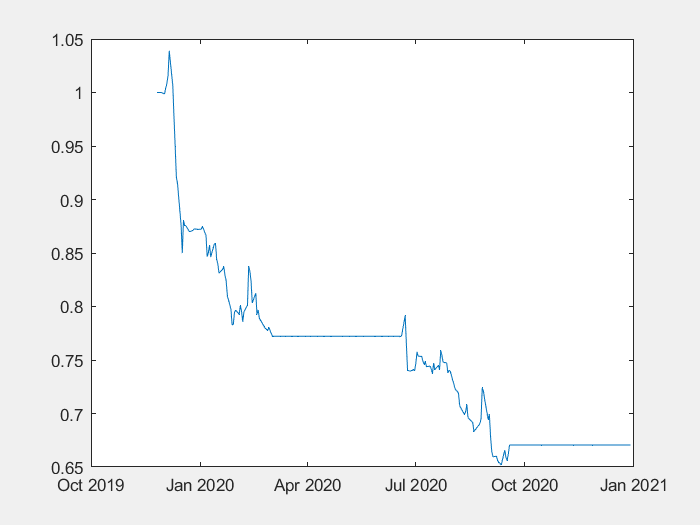

for i = 1:NumTrainTestSet

%      i = 4
    % Train & test set for each i
    % Train set idx i
    TrainsetStartdateIdxi = i ;
    TrainsetEnddateIdxi = TrainsetStartdateIdxi + NumStepTrainSet-1 ; % 1 is for adjustment
    
    % Test set idx i
    TestsetStartdateIdxi = TrainsetEnddateIdxi ;
    TestsetEnddateIdxi = TestsetStartdateIdxi + NumStepTestSet
    
    % Train dataset i
    PricesTTtrainDSi = PricesTTbtDataset (TrainsetStartdateIdxi:TrainsetEnddateIdxi, :)
    VolumesTTtrainDSi = VolumesTTbtDataset (TrainsetStartdateIdxi:TrainsetEnddateIdxi, :)
    
    % Test dataset i
    PricesTTtestDSi = PricesTTbtDataset (TestsetStartdateIdxi-LiquidSurgAvgLagDays:TestsetEnddateIdxi-1, :)
    VolumesTTtestDSi = VolumesTTbtDataset (TestsetStartdateIdxi-LiquidSurgAvgLagDays-1, :)
    
    % Optimize x parameters in Train dataset 
    % surrogateopt for expensive optim problems
    % Assign IST dataset
    PricesISTi = PricesTTtrainDSi ;
    VolumesISTi = VolumesTTtrainDSi ;

    fun = @(x) TrendTradingFcnMultiVarSharpe (x, PricesISTi, VolumesISTi) ;
    nvars = 7 ;
    lb = [10^3	10^6 -10  1	1	25 -8] ;
    ub = [10^15 10^15	80 10^15 10^15 80 80 ] ;
    intcon = 1:nvars ;
    NumFunctionEvaluations = 40 ; % Set different value for development or live stage
    options = optimoptions('surrogateopt','PlotFcn',"surrogateoptplot", ...
        "ConstraintTolerance",1e-2,'UseParallel', true, ...
        'MaxFunctionEvaluations', NumFunctionEvaluations, "Display","iter");
    
    [xSharpeSur,fvalm,~,~,pop] = surrogateopt(fun,lb,ub,intcon,options) ;
    xSharpeSurOptimizedi = xSharpeSur ;
    
    % Save xOptimized per at each i cycle for each trainset )i row, size(x) column
    xOptimized (i,:) = xSharpeSurOptimizedi ;
    
    % Apply xOptimized to testset at each i cycle 
    % Assign OST dataset
    PricesOSTi = PricesTTtestDSi ; 
    VolumesOSTi = VolumesTTtestDSi ; 
    xOptimizedOSTi = xOptimized (i,:) ;
    
    dailyRetTestseti = TrendTradingFcnMultiVarDailyRetGraph (xOptimizedOSTi, ...
        PricesOSTi, VolumesOSTi)
    
    rowLengthi = size (dailyRetTestseti,1) 
    
    dailyRetTestset (max(i,rowLengthi*(i-1))+1:max(i,rowLengthi*(i-1))+rowLengthi, :) ;
    dailyRetTestseti ;
    dailyRetTestset (max(i,rowLengthi*(i-1))+1:max(i,rowLengthi*(i-1))+rowLengthi, :) = dailyRetTestseti ;
        
    % Plot test set backtest results
    dailyRetTestsetProgress = dailyRetTestset (1:i*rowLengthi, :) ;
    PortfolioValueTestSet = ret2tick (dailyRetTestsetProgress) ;
    plot (PortfolioValueTestSet.Time, PortfolioValueTestSet.Variables)

end

Save the xOptimized

 save ('TrendTradingWFA.mat', 'xOptimized', 'PricesTTFullRaw', 'VolumesTTFullRaw')
 

Close

toc
